# Motor Data Processing 

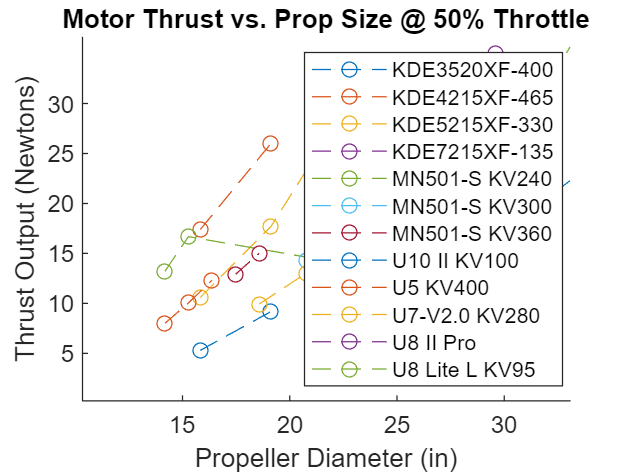

% house keeping
clc; clear; close all;
% Load Data
Motor_Names = ["KDE3520XF-400","KDE4215XF-465","KDE5215XF-330","KDE7215XF-135" ...
    "MN501-S KV240","MN501-S KV300","MN501-S KV360","U10 II KV100","U5 KV400","U7-V2.0 KV280","U8 II Pro","U8 Lite L KV95"];

for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    PropD = Motor_Matrix(:,1);
    Thrust = Motor_Matrix(:,2)*0.009807; %convert Grams to Newtons
    figure(1)
    hold on
    title('Motor Thrust vs. Prop Size @ 50% Throttle')
    xlabel('Propeller Diameter (in)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

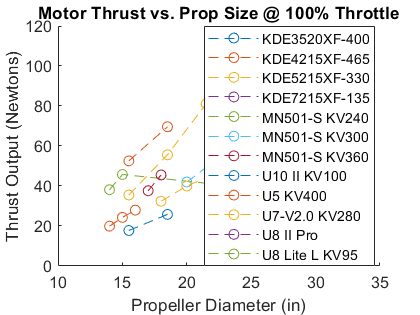


%%---------------------------------------------

for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(2)
    Thrust = Motor_Matrix(:,3)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,1);
    hold on
    title('Motor Thrust vs. Prop Size @ 100% Throttle')
    xlabel('Propeller Diameter (in)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")